## Set parameters

In this script we will demonstrate scattering of an incident plane wave with direction (1,0) and wavelength $\lambda$ by a circular scatterer with radius $\rho$ and centre $\mathbf{0}$. In this script we apply the sound-soft boundary condition on the boundary of the scatterer.

First we will setup the parameters $\lambda$ and $\rho$ that determine the scattering problem.

lambda = 2;

rho = 1;

Note: in the code we will represent vectors $(x,y)$ by complex numbers $x + yi$.

## Set dependent parameters

Set the wavenumber based on the incident wavelength

        $k = \frac{2 \pi}{\lambda}$.

kwave = 2*pi/lambda;

This is also a good time to setup the incident wave $u^{inc}(\mathbf{x}) = e^{i k \mathbf{x} \cdot (1,0)}$ with direction $(\cos 0,\sin 0)$:

uinc = plane_wave(0,kwave);

## Setup T-matrix

To simulate scattering we will use the T-matrix with order $n$ chosen by Wiscombe's formula

        $n \approx  x + 4x^{1/3} + 1$,

where $x = k\rho$ and $\rho$ is the scatterer radius.

n = suggestedorder(kwave,rho);

Because, the scatterer is circular, its T-matrix $T$ is known analytically and there are special TMATROM functions to set it up.

T = mie_tmatrix(kwave,rho,n,'SOFT');

## Scattering simulation

We will represent the incident field by a regular wavefunction expansion

        $u^{inc}(\mathbf{x}) = \sum_{|l| \leq n} a_l J_{|l|}(kr) e^{ik \theta}$,

of the incident wave. Here $(r,\theta)$ are polar coordinates for $\mathbf{x}$. 

Let us get the regular wavefunction expansion coefficidents $a$ representing the incident wave $u^{inc}$ with local origin $\mathbf{0}$.

a = regularwavefunctionexpansion(n,0,uinc);

We will represent the scattered field as

        $u(\mathbf{x}) = \sum_{|l| \leq n} b_l H^{(1)}_{|l|}(kr) e^{ik \theta}$.

Using the T-matrix, we have

        $b = T a$,

where we have written $a=(a_l)$ and $b=(b_l)$.

b = T * a;

### Computing and plotting the far field

Next we will plot the far field at equally spaced directions on the unit circle, corresponding to equally spaced angles in the interval $[0,2\pi]$. First we set up the vector of directions.

theta = linspace(0,2*pi,1000);
z = exp(1i*theta);

Then we evalute the far field at these points using the radiating wavefunction expansion $b$.

f = b.evaluateFarField(z);

Finally we plot the far field.

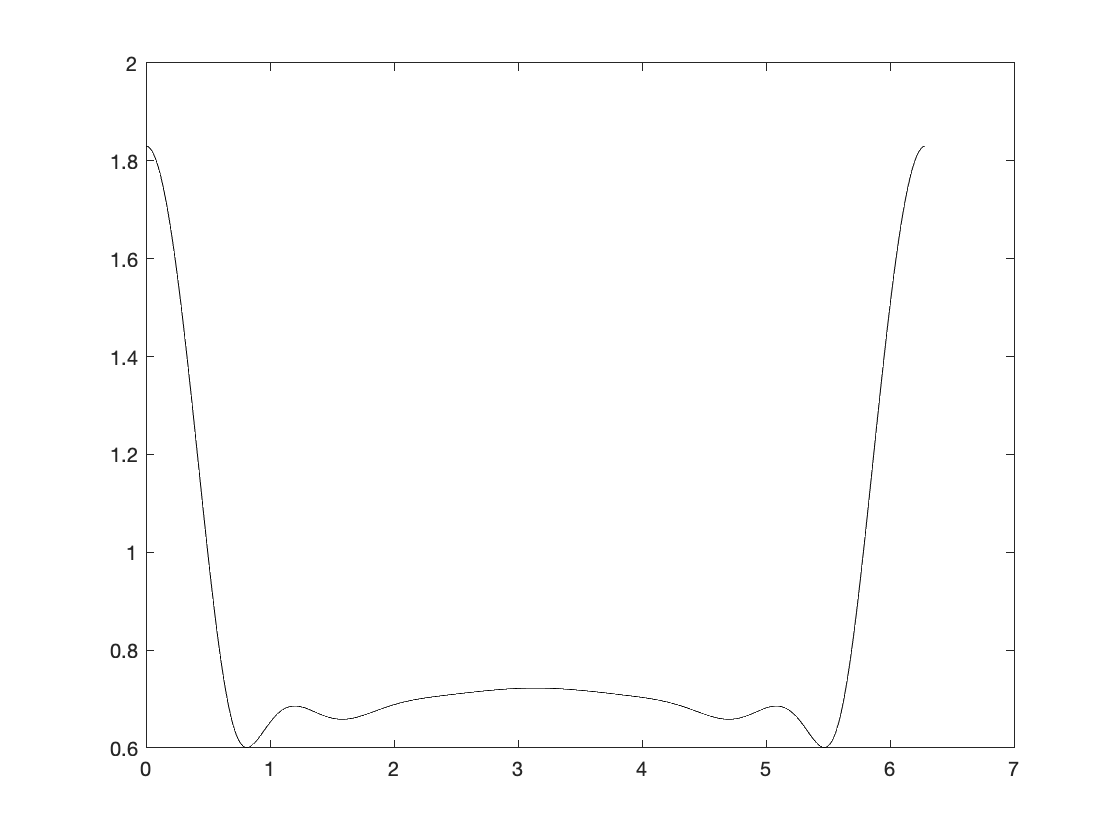

plot(theta,abs(f),'k-')

### Computing and plotting the total field

Finally, we will plot the total field on a domain containing the scatterer. To do this we first need to choose the domain and setup the mesh points. 

We will use a square domain $[-L,L] \times [-L,L]$ where $L = 5 \lambda$.

L = 5 * lambda;

We will choose the number of points $m$ in each direction of the mesh so that we have ten points per wavelength in each direction.

ppw = 10;
m = ceil(ppw*2*L/lambda);

Now create a mesh of the domain and get the points in complex-number format.

[x,y] = meshgrid(linspace(-L,L,m));
z = x + 1i * y;

Then we evaluate the total field at the mesh points using the radiating wavefunction expansion $b$, and the incident field $u^{inc$.

u = b.evaluate(z) + uinc.evaluate(z);

The radiating wavefunction expansion is valid only outside the scatterer, so we apply a mask to the total field to ensure the field inside the scatterer is not plotted.

u(abs(z) < rho) = NaN;

Finally we plot the field, and make the figure look nice.

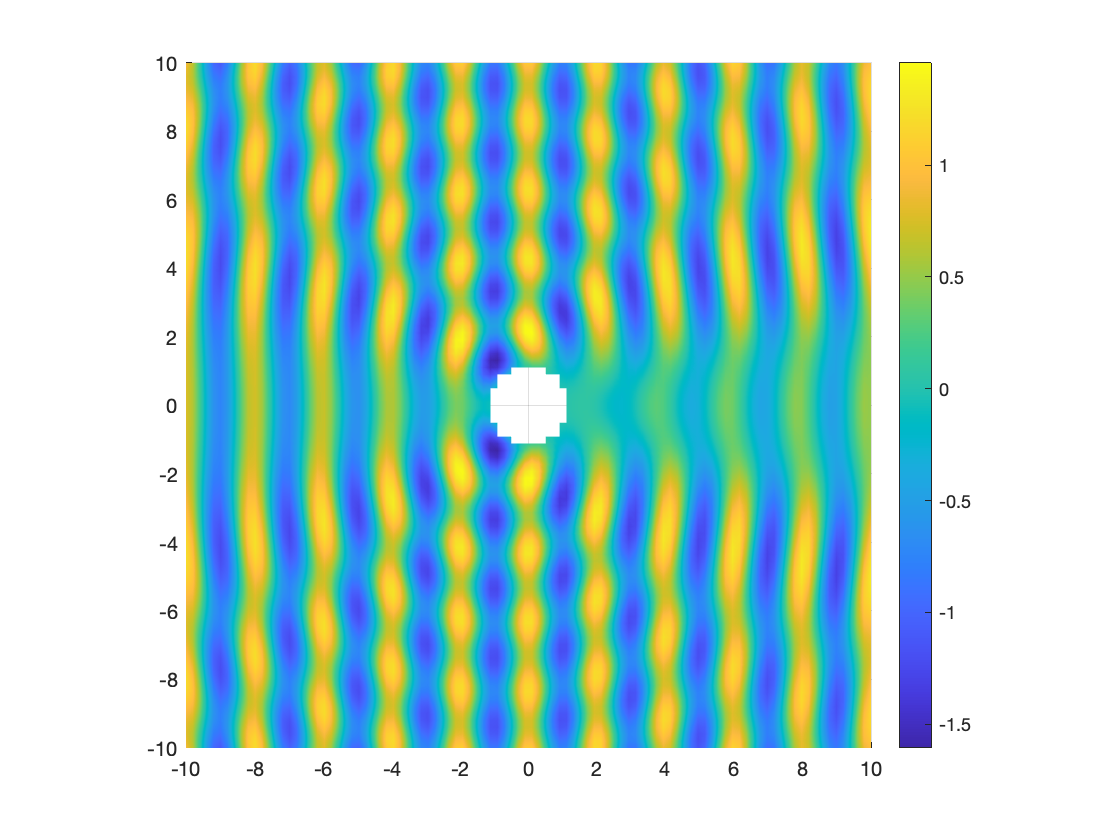

figure
surf(x,y,zeros(size(u)),real(u));
shading interp
axis equal
view([0 90])
colorbar